# 포트 설정

% MATLAB 코드: ESP32로부터 CIR 데이터 수신 및 시각화 + 칼만 필터 적용
serialPort = 'COM7';  % ESP32가 연결된 포트 (Windows 기준, Linux는 /dev/ttyUSB0 등)
baudRate = 115200;     % ESP32의 Serial 통신 속도

# 데이터 수집(Serial 통신)

% Serial 객체 생성 및 열기
s = serialport(serialPort, baudRate);
configureTerminator(s, "LF");  % 줄바꿈 문자 기준으로 데이터 수신

% 데이터 저장용 배열 초기화
realData = [];
imagData = [];

disp('데이터 수신 중...');

데이터 수신 중...



while true
    line = readline(s);

    % "CIR end" 메시지를 받으면 수신 중단
    if contains(line, "CIR end")
        break;
    end
    
    % 데이터가 실수부, 허수부 형식인지 확인
    if contains(line, ",")
        data = split(line, ",");
        realPart = str2double(data(1));
        imagPart = str2double(data(2));

        % 데이터 출력
        % disp(realPart);
        % disp(imagPart);
        if ~isnan(realPart) %초기 쓰레기값 분류
            % 데이터 저장
            realData = [realData; realPart];
            imagData = [imagData; imagPart];
        end
    end
end

% Serial 포트 닫기
clear s;

disp('데이터 수신 완료.');

데이터 수신 완료.



dataFilename = sprintf('Data.txt');
writematrix([realData,imagData], dataFilename);

# 필터링 적용

% 칼만 필터 파라미터 설정
Q = 1e-4;
R = 1e-3;
P_init = 1;

% 칼만 필터 적용
[filteredRealData, filteredImagData] = applyKalmanFilter(realData, imagData, Q, R, P_init);

% 이동 평균 필터 파라미터 설정
windowSize = 7;

% 이동 평균 필터 적용
[mafFilterRealData, mafFilterImagData] = applyMovingAverageFilter(realData, imagData, windowSize);

% 전체 필터 적용
[allFilterRealData, allFilterImagData] = applyMovingAverageFilter(filteredRealData, filteredImagData, windowSize);

# 원본 및 필터링 데이터 플롯

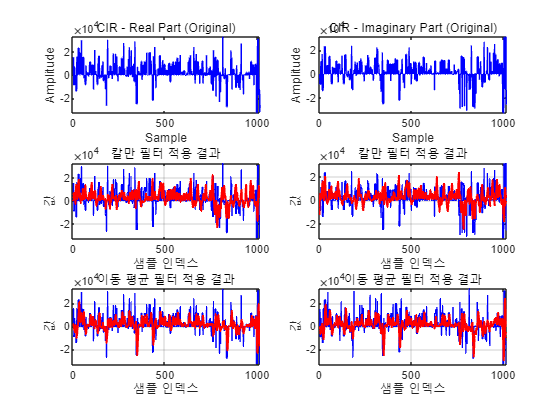

% 시각화 - 2x2 배열로 배치
figure(1);

% 좌상단: 원본 실수부 데이터
subplot(3,2,1);
plot(realData, 'b'); % 원본 데이터 - 파란색
title('CIR - Real Part (Original)');
xlabel('Sample');
ylabel('Amplitude');

% 우상단: 원본 허수부 데이터
subplot(3,2,2);
plot(imagData, 'b'); % 원본 데이터 - 파란색
title('CIR - Imaginary Part (Original)');
xlabel('Sample');
ylabel('Amplitude');

% 좌하단: 칼만 필터링된 실수부 데이터
subplot(3,2,3);
plot(realData, '-b', 'DisplayName', '원본 데이터', 'LineWidth', 1);
hold on;
plot(kalmanFilterRealData, '-r', 'DisplayName', '칼만 필터 적용-실수부', 'LineWidth', 1.5);
%legend;
title('칼만 필터 적용 결과');
xlabel('샘플 인덱스');
ylabel('값');
grid on;

% 우하단: 칼만 필터링된 허수부 데이터
subplot(3,2,4);
plot(imagData, '-b', 'DisplayName', '원본 데이터', 'LineWidth', 1);
hold on;
plot(kalmanFilterImagData, '-r', 'DisplayName', '칼만 필터 적용-허수부', 'LineWidth', 1.5);
%legend;
title('칼만 필터 적용 결과');
xlabel('샘플 인덱스');
ylabel('값');
grid on;

% 좌하단: 이동 평균 필터링된 실수부 데이터
subplot(3,2,5);
plot(realData, '-b', 'DisplayName', '원본 데이터', 'LineWidth', 1);
hold on;
plot(mafFilterRealData, '-r', 'DisplayName', '이동 평균 필터 적용-실수부', 'LineWidth', 1.5);
%legend;
title('이동 평균 필터 적용 결과');
xlabel('샘플 인덱스');
ylabel('값');
grid on;

% 좌하단: 이동 평균 필터링된 허수부 데이터
subplot(3,2,6);
plot(realData, '-b', 'DisplayName', '원본 데이터', 'LineWidth', 1);
hold on;
plot(mafFilterImagData, '-r', 'DisplayName', '이동 평균 필터 적용-허수부', 'LineWidth', 1.5);
%legend;
title('이동 평균 필터 적용 결과');
xlabel('샘플 인덱스');
ylabel('값');
grid on;

# 필터 복수 적용

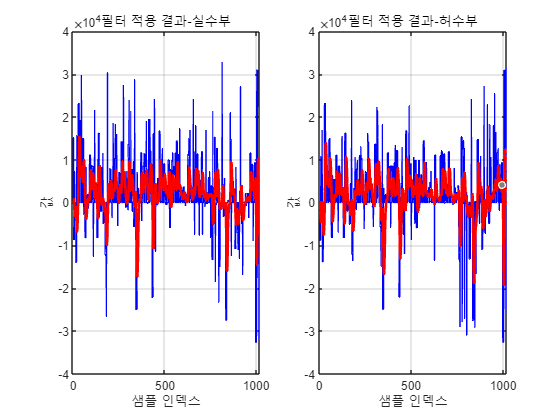

figure(2);

subplot(1,2,1);
plot(realData, '-b', 'DisplayName', '원본 데이터', 'LineWidth', 1);
hold on;
plot(allFilterRealData, '-r', 'DisplayName', '이동 평균 필터 적용 데이터', 'LineWidth', 2);
title('필터 적용 결과-실수부');
xlabel('샘플 인덱스');
ylabel('값');
grid on;


subplot(1,2,2);
plot(imagData, '-b', 'DisplayName', '원본 데이터', 'LineWidth', 1);
hold on;
plot(allFilterImagData, '-r', 'DisplayName', '이동 평균 필터 적용 데이터', 'LineWidth', 2);
title('필터 적용 결과-허수부');
xlabel('샘플 인덱스');
ylabel('값');
grid on;

# 복소수 선언

% 실수부와 허수부 데이터를 복소수로 결합
complexCIR = sqrt(realData.^2 + imagData.^2);

# 이동 평균 필터

% 이동 평균 필터
windowSize = 7; % 윈도우 크기 (평균을 낼 샘플 수)
b = (1/windowSize) * ones(1, windowSize);
a = 1;

% 이동 평균 필터 적용
filteredData = filter(b, a, complexCIR);
z = realData + 1i* imagData;

# 진폭 및 위상 플롯

% 방법 1: 진폭(Amplitude) 플롯
figure;
subplot(2,1,1);
plot(complexCIR, '-b', 'DisplayName', '원본 데이터', 'LineWidth', 1);
hold on;
plot(filteredData, '-r', 'DisplayName', '이동 평균 필터 적용 데이터', 'LineWidth', 2);
title('CIR Amplitude');
xlabel('Sample');
ylabel('Amplitude');

% 방법 2: 폴라 플롯 (위상 및 진폭 표현)
subplot(2,1,2);
polarplot(angle(z), abs(z), '.');
title('CIR Polar Plot');

# Figure 저장

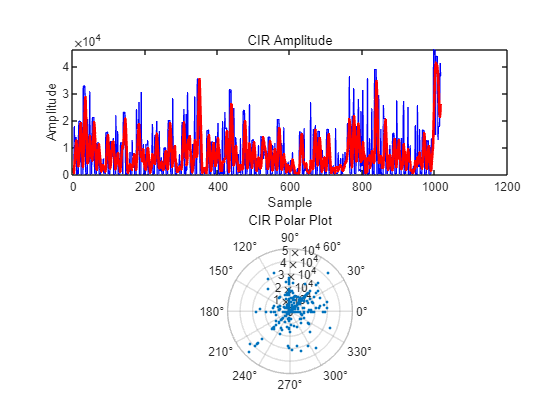

% Figure를 JPEG 파일로 저장하기
figureFilename = sprintf('Figure%d.jpg');
saveas(gcf, figureFilename);   % 필터링된 데이터를 'CIR_Data_Filtered.jpg'로 저장

disp('시각화 완료 및 JPEG 파일로 저장되었습니다.');

시각화 완료 및 JPEG 파일로 저장되었습니다.


# 칼만 필터 함수

function [filteredRealData, filteredImagData] = applyKalmanFilter(realData, imagData, Q, R, P_init)
    % applyKalmanFilter: 실수부와 허수부 데이터를 각각 칼만 필터링 처리
    % 입력:
    %   realData: 실수부 데이터
    %   imagData: 허수부 데이터
    %   Q: 프로세스 잡음 공분산
    %   R: 측정 잡음 공분산
    %   P_init: 초기 오차 공분산
    % 출력:
    %   filteredRealData: 필터링된 실수부 데이터
    %   filteredImagData: 필터링된 허수부 데이터

    % 필터링된 데이터 저장용 배열 초기화
    filteredRealData = zeros(size(realData));
    filteredImagData = zeros(size(imagData));

    % 초기 상태 설정
    realEstimate = realData(1);
    imagEstimate = imagData(1);
    P = P_init;

    % 실수부 및 허수부에 각각 칼만 필터 적용
    for i = 1:length(realData)
        % 예측 단계
        realPrediction = realEstimate;
        imagPrediction = imagEstimate;
        P = P + Q;

        % 칼만 이득 계산
        K = P / (P + R);

        % 현재 측정값이 유효한지 확인
        if ~isnan(realData(i))
            realEstimate = realPrediction + K * (realData(i) - realPrediction);
        else
            realEstimate = realPrediction;  % NaN인 경우 이전 예측값 유지
        end

        if ~isnan(imagData(i))
            imagEstimate = imagPrediction + K * (imagData(i) - imagPrediction);
        else
            imagEstimate = imagPrediction;  % NaN인 경우 이전 예측값 유지
        end

        % 오차 공분산 갱신
        P = (1 - K) * P;

        % 필터링된 데이터 저장
        filteredRealData(i) = realEstimate;
        filteredImagData(i) = imagEstimate;
    end
end


% disp(filteredRealData);
% disp(filteredImagData);

# 이동 평균 필터 함수

function [mafFilterRealData, mafFilterImagData] = applyMovingAverageFilter(realData, imagData, windowSize)
    % applyMovingAverageFilter: 이동 평균 필터를 실수부와 허수부 데이터에 각각 적용
    % 입력:
    %   realData: 실수부 데이터
    %   imagData: 허수부 데이터
    %   windowSize: 이동 평균 윈도우 크기 (평균을 낼 샘플 수)
    % 출력:
    %   mafFilterRealData: 필터링된 실수부 데이터
    %   mafFilterImagData: 필터링된 허수부 데이터

    % 이동 평균 필터 계수 설정
    b = (1/windowSize) * ones(1, windowSize);
    a = 1;

    % 이동 평균 필터 적용
    mafFilterRealData = filter(b, a, realData);
    mafFilterImagData = filter(b, a, imagData);

    % % 결과 시각화
    % figure;
    % plot(realData, '-b', 'DisplayName', '원본 데이터', 'LineWidth', 1);
    % hold on;
    % plot(mafFilterRealData, '-r', 'DisplayName', '이동 평균 필터 적용 데이터', 'LineWidth', 2);
    % legend;
    % title('이동 평균 필터 적용 결과');
    % xlabel('샘플 인덱스');
    % ylabel('값');
    % grid on;
end